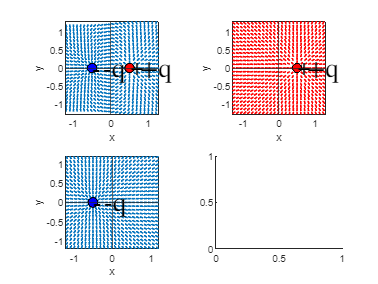

clear;
clf;

% Valores de las variables
xi = input('Coordenada x: ');
yi = input('Coordenada y: ');
xf = input('Coordenada x: ');
yf = input('Coordenada y: ');
eps0 = 8.854e-12;
k = 1/(4*pi*eps0);
q1 = 0.5 *10^(-12);
q2 = -0.5 *10^(-12);

% Crea el grid
x = linspace(-1.2,1.2,25);
y = linspace(-1.2,1.2,25);
z = linspace(-1.2,1.2,25);
[gx, gy, gz] = meshgrid(x,y,z);


% Vectores de la carga al punto de observación
Vx = gx - xi;
Vy = gy - yi;

Vx2 = gx - xf;
Vy2 = gy - yf;

% Magnitudes de los vectores
v1m = sqrt(Vx.^2 + Vy.^2).^3;
v2m = sqrt(Vx2.^2 + Vy2.^2).^3;

% Calculo de los campos electricos
Ex1 = k*q1*(Vx)./ v1m;
Ey1 = k*q1*(Vy)./ v1m;

Ex2 = Ex1 + k*q2*(Vx2)./v2m;
Ey2 = Ey1 + k*q2*(Vy2)./v2m;

Ex3 = k*q2*(Vx2)./v2m;
Ey3 = k*q2*(Vy2)./v2m;

% Magnitud de campos
E1 = sqrt(Ex1.^2 + Ey1.^2);
E2 = sqrt(Ex2.^2 + Ey2.^2);
E3 = sqrt(Ex3.^2 + Ey3.^2);

% Vectores unitarios
u1= Ex1./E1;
v1 = Ey1./E1;
u2 = Ex2./E2;
v2 = Ey2./E2;
u3 = Ex3./E3;
v3 = Ey3./E3;

% Plot de los campos
% Campo con ambas cargas
subplot(2,2,1)
quiver(x,y,u2,v2,"LineWidth",1.5,'AutoScaleFactor',0.8)

rectangle("Position",[xi-0.125 yi-0.125 0.25 0.25],"Curvature",[1 1],"FaceColor","r");
rectangle("Position",[xf-0.125 yf-0.125 0.25 0.25],"Curvature",[1 1],"FaceColor","b");
text(xi,yi,"+",'FontSize',22.5)
text(xi+0.2,yi,"+q",'FontSize',25,'Interpreter','latex')
text(xf,yf,"-",'FontSize',22.5)
text(xf+0.2,yf,"-q",'FontSize',25,'Interpreter','latex')
xline(0)
yline(0)
xlabel("x")
ylabel("y")
pbaspect([1 1 1])

% Campo con carga positiva
subplot(2,2,2)
t = quiver(x,y,u1,v1,"LineWidth",1.5,'AutoScaleFactor',0.8);
set(t,'color','r')
rectangle("Position",[xi-0.125 yi-0.125 0.25 0.25],"Curvature",[1 1],"FaceColor","r");
text(xi,yi,"+",'FontSize',22.5)
text(xi+0.2,yi,"+q",'FontSize',25,'Interpreter','latex')
xline(0)
yline(0)
xlabel("x")
ylabel("y")
pbaspect([1 1 1])

% Campo con carga negativa
subplot(2,2,3)
quiver(x,y,u3,v3,"LineWidth",1.5,'AutoScaleFactor',0.8)
rectangle("Position",[xf-0.125 yf-0.125 0.25 0.25],"Curvature",[1 1],"FaceColor","b");
text(xf,yf,"-",'FontSize',22.5)
text(xf+0.2,yf,"-q",'FontSize',25,'Interpreter','latex')
xline(0)
yline(0)
xlabel("x")
ylabel("y")
pbaspect([1 1 1])
subplot(2,2,4)


% Campo con streamslice
%subplot(2,2,4)
%streamslice(x,y,z,u1,v1,gz,"LineWidth",1.5,'AutoScaleFactor',0.8)